# Title

Sofia Ramos, Derek Martielli

## Question

## What percent of infected individuals need to quarantine to cut the peak of super spreading diseases by 50%? 

This is a moderately general rhetorical question. While we are aiming to find specific values, the scenario we are constructing does not directly reflect any one disease. We are not able to directly affect how many people quarantine but it our results can help inform personal decisions. Our modeling question is important as it pinpoints the effectiveness of quarantining in reducing the number of infections of super spreading diseases. Understanding how to prevent the spread of a disease is crucial as diseases negatively impact the health of individuals. 

Much of our research was on modeling COVID-19. This is because COVID-19 is a disease that famously spreads through super spreading events (cite althouse). None of the research directly answers our question, but it does provide a framework for modeling and results we can expect.

## Methodology/Model

Our model uses a stochastic agent based SIEQR.

Our model makes the assumptions that individuals aren’t vaccinated, there’s connections within the population and quarantine is correctly implemented. Some limitations that these assumptions impose is the model being unable to produce an outcome of how effective quarantine is with the addition of vaccinations and a result of not following quarantine procedures correctly. We’re able to bypass these limitations by rationalizing that vaccinations are typically produced significantly after a disease is introduced, limiting our data. When considering following quarantine procedures, we’re able to model accuracy by expecting that all individuals properly follow guidelines. 

Here is the breakdown of our model:

The model takes 6 total parameters:

recovery_rate = 0.25;                            % Chance to recover each timestep
n_population = 1000;                              % Population size
quarantine_percent = 0.5;                      % Percent of infected people who quarantine each timestep
R0 = 2.6;                                                % Disease reproduction number
k = 0.16;                                                 % Disease dispersion
Iv1 = zeros(n_population, 1); Iv1(1) = 1;  % Initial infection vector with one person infected
Timesteps = 100;                                    %Timesteps to run

Besides quarantine percent, all of these values will be the same throughout the entire paper. Many of the parameters were set using real world data from COVID-19. We use COVID-19 data because it is well documented and a prime example of a disease that spreads through super spreading events (cite althouse). The recovery rate of 0.25 reflects COVID-19 recovery time of 4 days (cite). We use a population size of 1000 (CHANGE LATER) as it is the largest population we can reasonably simulate. Quarantine percent represents the an infected individuals chance to enter quarantine each timestep. Here it is set to 0.5 or 50% but it is swept in our final simulation. For the negative binomial disease spread we use mean (R₀) of 2.6 and a dispersion parameter (k) of 0.16. These values are from the (cite Althouse) paper and are chosen to reflect COVID-19's spread. The vector Iv1 represents the initial infection state of the model. Right now it is set so that only person no.1 is infected. We run each simulation for 100 timesteps as all runs end well before this time is reached.

The model is primarily agent-based, with the states being: Susceptible, exposed, infected, quarantined, and recovered. 

The model starts by running some setup:

   % Generate NB distribution for use in the model
   R0 = 2.6;  % disease reproduction number
   k = 0.16;   % disease dispersion
   r = k;
   p = (k)/(R0+k); %WHAT IS P?????????????????????????????
   pd_sse = makedist('NegativeBinomial', 'r', r, 'p', p);  % Negative Binomial distribution

Visualized, the distribution looks like this:

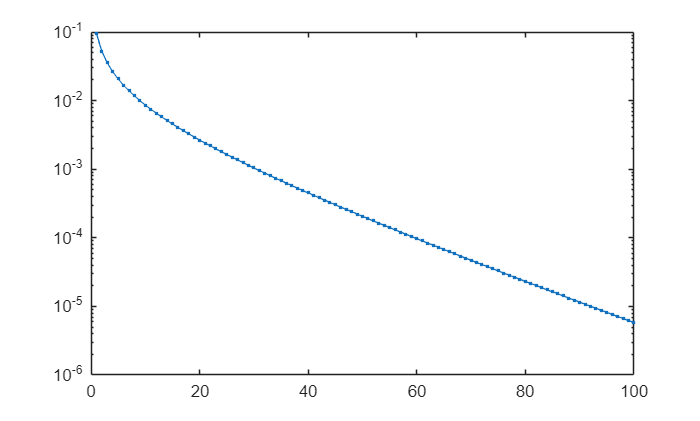

semilogy(1:100, pdf(pd_sse, 1:100), '.-', 'DisplayName', 'Negative '); 

Step 1 of the action is to calculate the amount of new infections.

  % Compute infections with NB distribution
       R0 = 2.6;
       r = 0.16;
       p = (r)/(R0+r);
       pd_sse = makedist('NegativeBinomial', 'r', r, 'p', p);  % Negative Binomial distribution

The chance for a person to quarantine is not set to a single value as this is the variable we sweep.

We validated our model (qualitatively?). Comparing some of our results with real infection graphs from covid-19 shows a similarity in how the infection peaks. Often there isn’t one sharp peak but a cluster of close together peaks. Looking at our results we can see similar behavior. We can also validate our results by seeing if we get similar results to some of the papers. The (rapid review?) paper showed that quarantining could eliminate 44-96% of cases. We can see if we are able to reach both ends of this result by running the model with very high quarantine rates and moderate or low quarantine rates. NEED TO DO

## Results

Generate results

recovery_rate = 0.25;
n_population = 10000;

% One initial infected person
Iv1 = zeros(n_population, 1); Iv1(1) = 1;

% Set up simulation parameters
timestep = 100;

   % For loop
   for i = 1:100
      quarantine_percent = i/100; %percent varies
    for k = 1:10
        [Sh, Ih, Rh,Qh,Eh] = simulate_absir(Iv1, timestep, recovery_rate, quarantine_percent);
       I_ensemble(:, k) = sum(Ih, 1);
    end
      idx_takeoff = I_ensemble(10, :) > 0;
      I_takeoff = I_ensemble(:, idx_takeoff);
      peak_all  = max(mean(I_ensemble,2),[],1);
      Peak_history(i) = peak_all;
      % P_Values(i) = quarantine_percent; % Store quarantine percentage
      % Percent(i) = max(I_ensemble(:, 2)); % Store peak infected
   end

Graph results

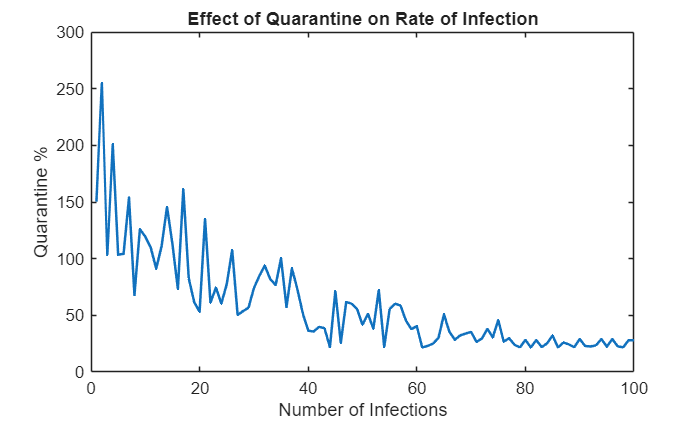

    figure
   plot(Peak_history,'LineWidth',1.5);
xlabel('Number of Infections')
ylabel('Quarantine %')
title('Effect of Quarantine on Rate of Infection')

TESTING STUFF (will delete later):

% Set up parameter values
recovery_rate = 0.25;
n_population = 1000;
quarantine_percent = 0.5;

% One initial infected person
Iv1 = zeros(n_population, 1); Iv1(1) = 1;

% Set up simulation parameters
n_realizations = 100;
Timesteps = 100;

% Generate the sample of results
I_ensemble = zeros(Timesteps, n_realizations);
S_ensemble = zeros(Timesteps, n_realizations);
R_ensemble = zeros(Timesteps, n_realizations);
Q_ensemble = zeros(Timesteps, n_realizations);
E_ensemble = zeros(Timesteps, n_realizations);

%Run simulation
for i = 1 : n_realizations
    [Sh, Ih, Rh,Qh,Eh] = simulate_absir(Iv1, Timesteps, recovery_rate, quarantine_percent);
    I_ensemble(:, i) = sum(Ih, 1);
    Q_ensemble(:, i) = sum(Qh, 1);
end

%Calculate stuff to find what cases "took off"
idx_takeoff = I_ensemble(10, :) > 0;
I_takeoff = I_ensemble(:, idx_takeoff);

%Average peak of all runs
peak_all  = max(mean(I_ensemble,2),[],1)

peak_all = 29.5100

%Average peak of runs that "took off"
peak_takeoff = max(mean(I_takeoff,2),[],1)

peak_takeoff = 92.1562

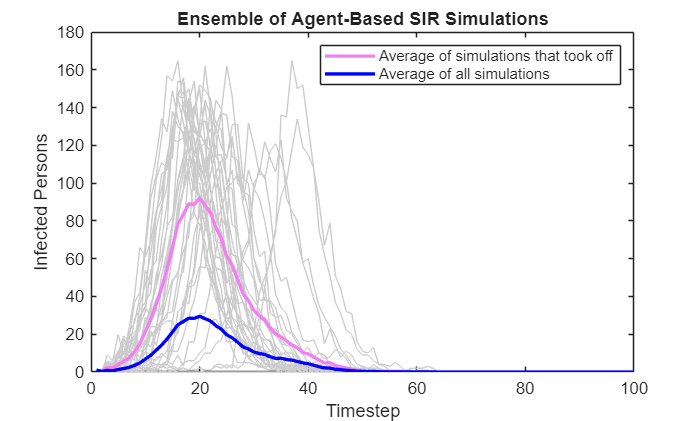


%Graph Stuff
plot(I_ensemble, 'k', "Color", [0.8, 0.8, 0.8, 0.2],'HandleVisibility','off');hold on;
plot(mean(I_takeoff,2), 'color', [0.95 0.5 0.95], 'LineWidth', 2);
plot(mean(I_ensemble, 2), 'b', 'LineWidth', 2);
legend('Average of simulations that took off','Average of all simulations');
hold off
xlabel('Timestep')
ylabel('Infected Persons')
title('Ensemble of Agent-Based SIR Simulations')


%plot(S_ensemble, 'k')
%plot(R_ensemble, 'k')
%plot(Q_ensemble, 'k')
%plot(E_ensemble, 'k')
